# Fast Cyclic Ankle DF - Individual Analysis.

Authors: F Cenni,[ francesco.cenni@gmail.com](mailto:francesco.cenni@gmail.com)>; P Valadao pvaladao@tuta.io

19/04/2022 - New version to analyze only peak torque in the common range of motion. 2 velocities calculated in three ways: 1) offset at ev1, 2) offset calculated at ev3, 3) offset at the beggining of the signal.

clc
clear all
close all

## Input and Load Data

dataPath = 'C:\Doutorado\Matlab\Paper II\TSRT\TSRT_smr\';
fileName = '5219_pre2_ST.smr';  
data = ImportSMR([dataPath fileName]);
Subject = string(fileName(1:4));
Group = "TD";
Test = "Pre2";
load add_info.mat %  table with latencies + MVC RMS for both muscle

## Data Trimming

A few data files are extremely long since data collection was not stopped at the end of the protocol, this section trims the dataset. 5108: 300000:end/ 5119 = 1:150000, 5202 = 1230000:end.

% data(1).imp.adc = data(1).imp.adc(300000:end);
% data(2).imp.adc = data(2).imp.adc(300000:end);
% data(3).imp.adc = data(3).imp.adc(300000:end);
% data(4).imp.adc = data(4).imp.adc(300000:end);

## Channel_1:Torque data [Nm]

information extracted from the struct **(read struct from smr data)****

f_sample_ch1=1/(data(1).hdr.adc.SampleInterval(1)*data(1).hdr.adc.SampleInterval(2));
variable_name_ch1=data(1).hdr.title;  %name of the variable
unit_ch1=data(1).hdr.adc.Units; %unit channel1
scale_factor_ch1=data(1).hdr.adc.Scale; %scaling factor for channel1
channel1=data(1).imp.adc; %signal 
N_samples_ch1=length(channel1); %number of samples
channel1_scaled=(double(channel1))*scale_factor_ch1; %scaling with double signal
time = N_samples_ch1/f_sample_ch1; %s
fprintf('the measurements took %d s\n',time);

the measurements took 1.463090e+02 s



%filter the data in channel1 (torque)
[b,a]=butter(6,40/(f_sample_ch1/2),'low'); %low-pass filter, order=6, cutoff freq= 40Hz
channel1_scaled_filt = filtfilt(b,a,channel1_scaled); %signal filtered (for outliers is better movmean)
% movemean filter
channel1_scaled_window = movmean(channel1_scaled,80); %where each mean is calculated over a sliding window

## Channel_2 (Angle)

f_sample_ch2 = 1/(data(2).hdr.adc.SampleInterval(1)*data(2).hdr.adc.SampleInterval(2));
% information extracted from the struct
variable_name_ch2=data(2).hdr.title;  
scale_factor_ch2=data(2).hdr.adc.Scale;
unit_ch2=data(2).hdr.adc.Units; %unit channel2
channel2=data(2).imp.adc;  
N_samples_ch2=length(channel2);
channel2_scaled_int=channel2*scale_factor_ch2;
channel2_scaled_d=(double(channel2))*scale_factor_ch2;% double format
% offset detection
starting_value_int=mean(channel2_scaled_int([1:200])); %average from first 200 samples
plantarflex_value_int=starting_value_int+20; %prior knowledge: always 20 deg in plantarflexion
starting_value_d=mean(channel2_scaled_d([1:200])); %average from first 200 samples (double)
plantarflex_value_d=starting_value_d+20; %

## Pre-signal processing (needed because there are some spikes on the angle-signal(int) +/-1 deg)

%indices
i=1;j=1;l=1;m=1;
for c = 1:N_samples_ch2
    if c == N_samples_ch2-200 % to avoid to exceed the N_samples_ch2 array
        break
    end
    if channel2_scaled_int(c) > plantarflex_value_int;
        channel2_scaled_int(c)=plantarflex_value_int;
    end
    if channel2_scaled_int(c) < starting_value_int;
        channel2_scaled_int(c)=starting_value_int;
    end
    if channel2_scaled_int(c) == starting_value_int+1;
        if channel2_scaled_int(c+200) < starting_value_int+2;
            channel2_scaled_int(c)=starting_value_int;
        end
    end
end
channel2_scaled_int = int8(medfilt1(double(channel2_scaled_int),150)); %further cleaning the signal
%detect offset from cleaned signal
starting_value_int=int8(mean(channel2_scaled_int([1:200])));
max_plantar_values_int= max(channel2_scaled_int);
plantarflex_value_int = int8(max_plantar_values_int); %from -real- max value

## Detecting the events from the angle signal

ev1:ankle is started to be plantarflexed / ev2: ankle is in plantarflexion / ev3: ankle is started to be dorsiflexed / ev4:ankle is back to dorsiflexion

for c = 1:N_samples_ch2
    if channel2_scaled_int(c) == starting_value_int+1
        if channel2_scaled_int(c-1) == starting_value_int
            % --ev1-- first event trapezoidal wave form (ankle is started to be plantarflexed)    
            index_ev1(i)=c-1;
            i=i+1;
        end
        if channel2_scaled_int(c+1) == starting_value_int
            % --ev4-- forth event trapez wave form (ankle is now in dorsiflexion)    
            index_ev4(j)=c+1;
            j=j+1;
        end
    end
    if channel2_scaled_int(c) == plantarflex_value_int;
        if channel2_scaled_int(c-1) == plantarflex_value_int-1;
            % --ev2-- second event trapez wave form (ankle is now in plantarflexion)    
            index_ev2(l)=c;
            l=l+1;
        end
        if channel2_scaled_int(c+1) == plantarflex_value_int-1;
            % --ev3-- third event trapez wave form (ankle is started to be dorsiflexed)  
            index_ev3(m)=c;
            m=m+1;
        end
    end
end

## Dorsi/Plantar flexion VELOCITIES [deg/sample]

!!the sequence for the velocities is the same every time!!

for ii = 1:length(index_ev1)
    % it should be always the same
    plantarflex_vel(ii)=20/(index_ev2(ii)-index_ev1(ii));
    % it should be 4 different velocities
    dorsiflex_vel(ii)=20/(index_ev4(ii)-index_ev3(ii));
% velocities classified using 1-2-3-4
    if dorsiflex_vel(ii)<0.06 %thresholds are in deg/sample
       vel_classification(ii)=1;
    elseif dorsiflex_vel(ii)<0.12
       vel_classification(ii)=2;
    elseif dorsiflex_vel(ii)<0.22
       vel_classification(ii)=3;
    else
       vel_classification(ii)=4;    
    end
end

%convert velocity in deg/s
plantarflex_vel_c = plantarflex_vel*f_sample_ch2;
dorsiflex_vel_c = dorsiflex_vel*f_sample_ch2;
%offset for the angle data (channel2_scaled_shifted)
angle_data = channel2_scaled_int - starting_value_int; %int format
angle_data_d = channel2_scaled_d - starting_value_d; %double format
angle_data_d_w = movmean(angle_data_d,10); % N=10 --> sample that is around 10ms; mean calculated over a sliding window

## Channels available for wired system

channel3=data(3).imp.adc; %soleus
channel4=data(4).imp.adc; %MG
channel3_d=double(channel3);%
channel4_d=double(channel4);%

## Channels avalable for wireless system

channel7=data(7).imp.adc; %soleus
channel8=data(8).imp.adc; %MG
channel7_d=double(channel7);%
channel8_d=double(channel8);%

## Pre-plots

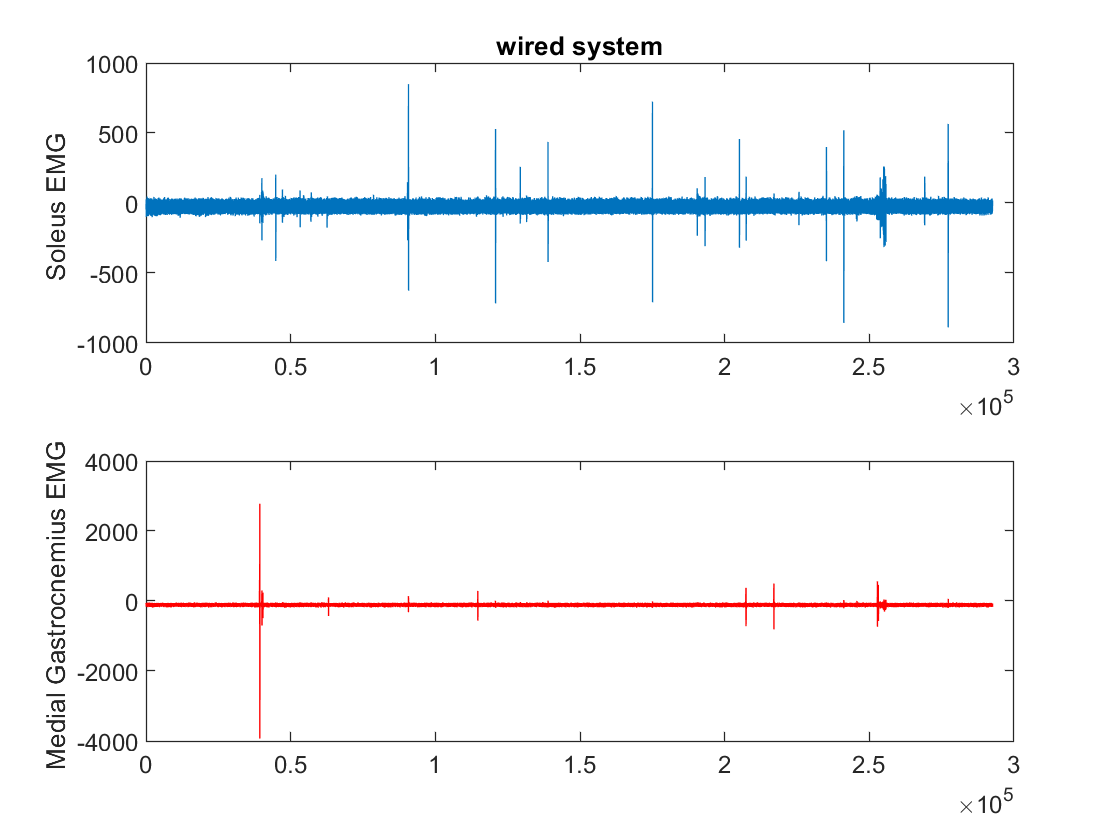

figure(1)
subplot(2,1,1)
plot(channel3)
ylabel('Soleus EMG ')
title('wired system')
hold on
subplot(2,1,2)
plot(channel4,'r')
ylabel('Medial Gastrocnemius EMG ')

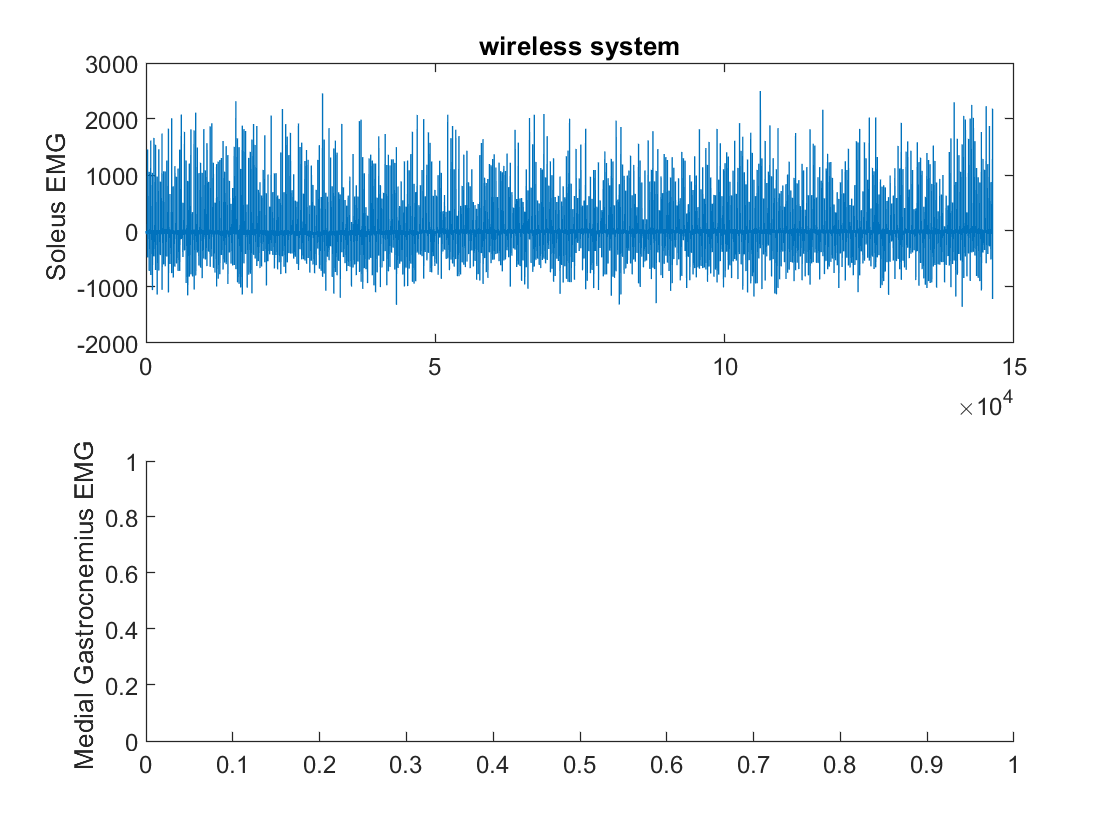

figure(2)
subplot(2,1,1)
plot(channel7)
ylabel('Soleus EMG ')
title('wireless system')
hold on
subplot(2,1,2)
plot(channel8,'r')
ylabel('Medial Gastrocnemius EMG ')

## Condition for selecting the type of EMG channel

filter parameters

%low-pass filter 
fcuthigh=195; %high cut frequency in Hz
[b1,a1]=butter(6,fcuthigh/(4000/2),'low'); %order=6, %fs=4000 
%bandpass
fcutlow=20;   %low cut frequency in Hz
fcuthigh=195;   %high cut frequency in Hz
[b0,a0]=butter(6,[fcutlow,fcuthigh]/(4000/2),'bandpass'); %order=6, %fs=4000 
% ---for envelope--- as in Bar-On 2014
% coefficients for filter; 30 Hz low-pass
[b,a]=butter(6,30/f_sample_ch2*2,'low');
typeEMG = input('Enter type EMG: ','s');

## --> Automatic latency input from table (file name=) add_info.mat

l_vec = strcmp(add_info.Subject,Subject);
[row, ~] = find(l_vec)

row =     30


latency_correction_sol = table2array(add_info(row, 6))

latency_correction_sol =     21


latency_correction_mg = table2array(add_info(row, 7))

latency_correction_mg =     22



%typeEMG=char(n);
switch typeEMG
    case 'wired'

        %%%---------------------channel 3 (WIRED channel SOLEUS)
        variable_name_ch3=data(3).hdr.title;  
        scale_factor_ch3=data(3).hdr.adc.Scale; 
        unit_ch3=data(3).hdr.adc.Units; %unit channel3
        channel3=data(3).imp.adc; 
        N_samples_ch3=length(channel3);
        channel3_d=double(channel3);
        channel3_scaled=channel3_d*scale_factor_ch3;
        freq_ratio = int8(N_samples_ch3./N_samples_ch2);  
        channel3_d2 = resample(channel3_scaled,1,double(freq_ratio)); %channel3_d
        channel3_filt = filtfilt(b0,a0,channel3_d2); %signal filtered
        
      
        %RMS envelope from EMG signal (as Bar-On 2014)
        emgrms_sol = sqrt( abs(filtfilt(b,a,channel3_d2.^2))+1E-14);
        %(rectfied emg signal)
        emgrms2_sol = sqrt(abs(channel3_filt.^2)+1E-14); %soleus
        % rms (from sqrt and ^2) of a sliding window (200ms),
        %using filtered emg signal, check example here https://it.mathworks.com/matlabcentral/answers/310418-how-do-i-calculate-the-rms-of-every-5-values
        emgrms_sol_mw_200_new = sqrt(movmean(channel3_filt.^2,200));

        %calculate RMS at resting periods, last 500ms before stretch (ALL) 
        for i = 1:length(index_ev2)
            %%from envelope 
            %emgrms_interval_plantar_sol_f=emgrms_sol((index_ev3(i)-500):index_ev3(i)); %last 500ms before stretch
            %avgs_emgrms_interval_plantar_sol_f(i)=mean(emgrms_interval_plantar_sol_f);            
            %from emg signal
            %emgrms_interval_plantar_sol=emgrms2_sol((index_ev3(i)-500):index_ev3(i)); %last 500ms before stretch
            %avgs_emgrms_interval_plantar_sol(i)=mean(emgrms_interval_plantar_sol);
            %maxs_emgrms_interval_plantar_sol_mw(i) = max(emgrms_sol_mw_200_new((index_ev3(i)-500):index_ev3(i))); %max among RMSs
            %
            % sol signal extracted for the relevant section
            emg_sol_cut = channel3_filt((index_ev3(i)-500):index_ev3(i));
            % M = movmean(A,3,'Endpoints','discard') ONLY full window average
            maxs_emgrms_interval_plantar_sol_mw(i) = max(sqrt(movmean(emg_sol_cut.^2,200,'Endpoints','discard'))); %200 win length
            
            % mean and std on the resting periods
            mean_emg_interval_plantar_sol1(i)=mean(channel3_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
            std_emg_interval_plantar_sol1(i)=std(channel3_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
        end

        %calculate RMS before (ALL) the stretches
        t_interv_dorsi_starting=index_ev1(1);
        %NEW: !correct version!
        emgrms_interval_dorsi_starting_sol_new=rms(channel3_filt(int16(t_interv_dorsi_starting)-1500:int16(t_interv_dorsi_starting)-500)); %1s     
        
        
        %--------------------------------------------------------------------------

        %%%---------------------channel 4 (wired channel MG)
        variable_name_ch4=data(4).hdr.title;  
        scale_factor_ch4=data(4).hdr.adc.Scale;
        unit_ch4=data(4).hdr.adc.Units; %unit channel4
        channel4=data(4).imp.adc;  
        N_samples_ch4=length(channel4);
        channel4_d=double(channel4);
        channel4_scaled=channel4_d*scale_factor_ch4;
        freq_ratio = int8(N_samples_ch4/N_samples_ch2);
        channel4_d2 = resample(channel4_scaled,1,double(freq_ratio)); %channel4_d
        channel4_filt = filtfilt(b0,a0,channel4_d2); %signal filtered
        
      
        %RMS envelope from EMG signal (as Bar-On 2014)
        emgrms_mg = sqrt( abs(filtfilt(b,a,channel4_d2.^2))+1E-14);
        %(rectfied emg signal)
        emgrms2_mg = sqrt(abs(channel4_filt.^2)+1E-14);
        %NEW: rms (from sqrt and ^2) of a sliding window (200ms),
        %using filtered emg signal, check example here https://it.mathworks.com/matlabcentral/answers/310418-how-do-i-calculate-the-rms-of-every-5-values
        emgrms_mg_mw_200_new = sqrt(movmean(channel4_filt.^2,200));

        %calculate RMS at resting periods, last 500ms before stretch
        for i = 1:length(index_ev2)
            % mg signal extracted for the relevant section
            emg_mg_cut = channel4_filt((index_ev3(i)-500):index_ev3(i));
            % M = movmean(A,3,'Endpoints','discard') ONLY full window average
            maxs_emgrms_interval_plantar_mg_mw(i) = max(sqrt(movmean(emg_mg_cut.^2,200,'Endpoints','discard')));
            % mean and std on the resting periods
            mean_emg_interval_plantar_mg1(i)=mean(channel4_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
            std_emg_interval_plantar_mg1(i)=std(channel4_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
        end

        %calculate RMS before the stretches     
        %NEW: !correct version!
        emgrms_interval_dorsi_starting_mg_new=rms(channel4_filt(int16(t_interv_dorsi_starting)-1500:int16(t_interv_dorsi_starting)-500)); %1s
        
    
    case 'wireless'
        
        %%%---------------------channel 7 (wireless channel SOLEUS)
        t_delay_ch7 = 200; %ms !!!-->the emg data have a constant delay of 200ms with respect angle data
        variable_name_ch7=data(7).hdr.title;  
        scale_factor_ch7=data(7).hdr.adc.Scale; %this seems not needed
        unit_ch7=data(7).hdr.adc.Units; %unit channel4
        channel7=data(7).imp.adc((t_delay_ch7+1):end); %cutting off the first 200ms
        channel7(end+1:end+t_delay_ch7)= 0; %filling with zeros to preserve vector length
        N_samples_ch7=length(channel7);
        channel7_d=double(channel7);
        channel7_scaled=channel7_d*scale_factor_ch7;
        freq_ratio = int8(N_samples_ch7./N_samples_ch2);  %% !!check var
        channel3_d2 = resample(channel7_scaled,1,double(freq_ratio));
        channel3_filt = filtfilt(b0,a0,channel3_d2); %signal filtered
       
        % coefficients for filter; 30 Hz low-pass
        [b,a]=butter(6,30/f_sample_ch2*2,'low');
        %RMS envelope from EMG signal (as Bar-On 2014)
        emgrms_sol = sqrt( abs(filtfilt(b,a,channel3_d2.^2))+1E-14);
        %(rectfied emg signal)
        emgrms2_sol = sqrt(abs(channel3_filt.^2)+1E-14);
        %NEW 2/3/21: rms (from sqrt and ^2) of a sliding window (200ms),
        %using filtered emg signal, check example here https://it.mathworks.com/matlabcentral/answers/310418-how-do-i-calculate-the-rms-of-every-5-values
        emgrms_sol_mw_200_new = sqrt(movmean(channel3_filt.^2,200));

        %calculate RMS at resting periods
        for i = 1:length(index_ev2)
            %NEW !CORRECT version!
            % sol signal extracted for the relevant section
            emg_sol_cut = channel3_filt((index_ev3(i)-500):index_ev3(i));
            % M = movmean(A,3,'Endpoints','discard') ONLY full window average
            maxs_emgrms_interval_plantar_sol_mw(i) = max(sqrt(movmean(emg_sol_cut.^2,200,'Endpoints','discard')));
            % mean and std on the resting periods
            mean_emg_interval_plantar_sol1(i)=mean(channel3_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
            std_emg_interval_plantar_sol1(i)=std(channel3_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
        end

        %calculate RMS before the stretches
        t_interv_dorsi_starting=index_ev1(1);
        %NEW 2/3/21: !correct version!
        emgrms_interval_dorsi_starting_sol_new=rms(channel3_filt(int16(t_interv_dorsi_starting)-1500:int16(t_interv_dorsi_starting)-500)); %1s

        
        %%%-----------------------------channel 8 (wireless channel Medial gastrocnemius)
        t_delay_ch8 = 200; %ms !!!-->the emg data have a constant delay of 200ms with respect angle data
        variable_name_ch8=data(8).hdr.title;  
        scale_factor_ch8=data(8).hdr.adc.Scale; %this seems not needed
        unit_ch8=data(8).hdr.adc.Units; %unit channel4
        channel8=data(8).imp.adc((t_delay_ch8+1):end); %cutting off the first 200ms
        channel8(end+1:end+t_delay_ch8)= 0; %filling with zeros to preserve vector length
        N_samples_ch8=length(channel8);
        channel8_d=double(channel8);
        channel8_scaled=channel8_d*scale_factor_ch8;
        freq_ratio = int8(N_samples_ch8./N_samples_ch2);  %% 
        channel4_d2 = resample(channel8_scaled,1,double(freq_ratio));       
        channel4_filt = filtfilt(b0,a0,channel4_d2); %signal filtered
      
		%RMS envelope from EMG signal (as Bar-On 2014)
        emgrms_mg = sqrt(abs(filtfilt(b,a,channel4_d2.^2))+1E-14);
        %(rectfied emg signal)
        emgrms2_mg = sqrt(abs(channel4_filt.^2)+1E-14);
        %NEW 2/3/21: rms (from sqrt and ^2) of a sliding window (200ms),
        %using filtered emg signal, check example here https://it.mathworks.com/matlabcentral/answers/310418-how-do-i-calculate-the-rms-of-every-5-values
        emgrms_mg_mw_200_new = sqrt(movmean(channel4_filt.^2,200));

        %calculate RMS at resting periods
        for i = 1:length(index_ev2)
            %NEW
            % mg signal extracted for the relevant section
            emg_mg_cut = channel3_filt((index_ev3(i)-500):index_ev3(i));
            % M = movmean(A,3,'Endpoints','discard') ONLY full window average
            maxs_emgrms_interval_plantar_mg_mw(i) = max(sqrt(movmean(emg_mg_cut.^2,200,'Endpoints','discard')));
            % mean and std on the resting periods
            mean_emg_interval_plantar_mg1(i)=mean(channel4_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
            std_emg_interval_plantar_mg1(i)=std(channel4_d2((index_ev3(i)-500):index_ev3(i))); %last 500ms before stretch
        end

        %%calculate RMS before the stretches
        t_interv_dorsi_starting=index_ev1(1);
        %NEW 2/3/21: !correct version!
        emgrms_interval_dorsi_starting_mg_new=rms(channel4_filt(int16(t_interv_dorsi_starting)-1500:int16(t_interv_dorsi_starting)-500)); %1s
        
end        
close all

## Condition related with MVC

%import data from add_info
emgrms_mvc_sol = table2array(add_info(row, 4))

emgrms_mvc_sol =         0.0731094764315218


emgrms_mvc_mg = table2array(add_info(row, 5))

emgrms_mvc_mg =          0.314620585522874


%
num_trials_sol_excluded=0; num_trials_mg_excluded=0; 
for i = 1:length(index_ev1)
    if maxs_emgrms_interval_plantar_sol_mw(i) > emgrms_mvc_sol*0.05
        cond_mvc_sol(i) = 0; % trials that will be excluded due to high EMG background
        num_trials_sol_excluded = num_trials_sol_excluded+1;
    else
        cond_mvc_sol(i) = 1; % trials with low EMG background
    end
    if maxs_emgrms_interval_plantar_mg_mw(i) > emgrms_mvc_mg*0.05
        cond_mvc_mg(i) = 0; % trials that will be excluded due to high EMG background
        num_trials_mg_excluded = num_trials_mg_excluded+1;        
    else
        cond_mvc_mg(i) = 1; % trials with low EMG background
    end           
end
fprintf('the total number of trials excluded for SOL is %.1i \n',num_trials_sol_excluded);

the total number of trials excluded for SOL is 0 


fprintf('the total number of trials excluded for MG is %.1i \n',num_trials_mg_excluded);

the total number of trials excluded for MG is 0 


## Torque/work/angles classified wrt stretch velocities (using mvc condition)

aa_sol=1;bb_sol=1;cc_sol=1;dd_sol=1;
%common angle (write here interval)
L1a=3.5;
L2a=16;
rom_com50 = zeros(length(index_ev1),2); %pre-allocation
rom_com100 = zeros(length(index_ev1),2); 
max_torque_com50_ev1_cond_mvc = zeros(10,1);
max_torque_com50_ev3_cond_mvc = zeros(10,1);
max_torque_com50_init_cond_mvc = zeros(10,1);
max_torque_com100_ev1_cond_mvc = zeros(10,1);
max_torque_com100_ev3_cond_mvc = zeros(10,1);
max_torque_com100_init_cond_mvc = zeros(10,1);
prestretch_torque_offset = mean(channel1_scaled_window([1:500])); %average from the last 200 samples before the first stretch
for ii = 1:length(index_ev1)
    prestretch_torque_offset_ev1(ii) = mean(channel1_scaled_window([index_ev1(ii)-200:index_ev1(ii)])); %average from the last 200 samples before the first stretch
    prestretch_torque_offset_ev3(ii) = mean(channel1_scaled_window([index_ev3(ii)-900:index_ev3(ii)-100])); %(ev3-900:ev3-100) --> for avoiding initial movement artefact of the torque channel 
end

for ii = 1:length(index_ev1)
    if dorsiflex_vel(ii)<0.06 & cond_mvc_sol(ii) == 1 %50deg/s and condition on MVC
       %common angle (in deg), 20ms per deg
       interv_torque_com50_L1_cond_mvc = index_ev3(ii)+ L1a*0.02*f_sample_ch1;
       interv_torque_com50_L2_cond_mvc = index_ev4(ii) - (20-L2a)*0.02*f_sample_ch1;
       torque_interval_com50_cond_mvc = channel1_scaled_window(int32(interv_torque_com50_L1_cond_mvc):int32(interv_torque_com50_L2_cond_mvc));    
       max_torque_com50_ev1_cond_mvc(aa_sol) = max(torque_interval_com50_cond_mvc)-prestretch_torque_offset_ev1(ii); %%OFFSET ADDED!
       max_torque_com50_ev3_cond_mvc(aa_sol) = max(torque_interval_com50_cond_mvc)-prestretch_torque_offset_ev3(ii); %%OFFSET ADDED!
       max_torque_com50_init_cond_mvc(aa_sol) = max(torque_interval_com50_cond_mvc)-prestretch_torque_offset; %%OFFSET ADDED!
       aa_sol=aa_sol+1;
       rom_com50(ii,1) = interv_torque_com50_L1_cond_mvc; %first col will have all samples where the common rom starts
       rom_com50(ii,2) = interv_torque_com50_L2_cond_mvc; %second col will have all samples where the common rom ends
    elseif dorsiflex_vel(ii)<0.12 & cond_mvc_sol(ii) == 1 %100deg and condition on MVC
       %common angle (in deg), 10ms per deg
       interv_torque_com100_L1_cond_mvc = index_ev3(ii)+ L1a*0.01*f_sample_ch1;
       interv_torque_com100_L2_cond_mvc = index_ev4(ii)- (20-L2a)*0.01*f_sample_ch1;
       torque_interval_com100_cond_mvc = channel1_scaled_window(int32(interv_torque_com100_L1_cond_mvc):int32(interv_torque_com100_L2_cond_mvc));
       max_torque_com100_ev1_cond_mvc(bb_sol) = max(torque_interval_com100_cond_mvc)-prestretch_torque_offset_ev1(ii);
       max_torque_com100_ev3_cond_mvc(bb_sol) = max(torque_interval_com100_cond_mvc)-prestretch_torque_offset_ev3(ii);
       max_torque_com100_init_cond_mvc(bb_sol) = max(torque_interval_com100_cond_mvc)-prestretch_torque_offset; %%OFFSET ADDED!
       bb_sol=bb_sol+1;
       rom_com100(ii,1) = interv_torque_com100_L1_cond_mvc; %first col will have all samples where the common rom starts
       rom_com100(ii,2) = interv_torque_com100_L2_cond_mvc; %second col will have all samples where the common rom ends
    elseif dorsiflex_vel(ii)<0.23  & cond_mvc_sol(ii) == 1 %200deg/s and condition on MVC
       cc_sol=cc_sol+1;
    elseif cond_mvc_sol(ii) == 1
       dd_sol=dd_sol+1; 
    end
end

## Results 3

Peak torque and energy calculated in the stretches at 50 and 100 deg/s. Torque offset was subtracted at 20 deg of PF (index_ev3).

Subject(1:10,1) = Subject;
Group (1:10,1) = Group;
Test (1:10,1) = Test;
Trial = (1:10)';
PT50_ev1 = max_torque_com50_ev1_cond_mvc; 
PT50_ev3 = max_torque_com50_ev3_cond_mvc; 
PT50_init = max_torque_com50_init_cond_mvc;
PT100_ev1 = max_torque_com100_ev1_cond_mvc;
PT100_ev3 = max_torque_com100_ev3_cond_mvc;
PT100_init = max_torque_com100_init_cond_mvc;
TSRT_mechanics = table(Subject,Group,Test,Trial,PT50_ev1,PT50_ev3, PT50_init, PT100_ev1,PT100_ev3, PT100_init)

TSRT_mechanics = 10×10 table
    Subject    Group     Test     Trial         PT50_ev1               PT50_ev3             PT50_init              PT100_ev1             PT100_ev3             PT100_init     
    _______    _____    ______    _____    ___________________    __________________    __________________    ___________________    __________________    ___________________

    "5219"     "TD"     "Pre2"      1        0.076824003786824    -0.796138626338665    -0.437481748757863    -0.0766042018116946    -0.117072957949309     -0.273937510736731
    "5219"     "TD"     "Pre2"      2      -0.0779384383624788    -0.498181708599542    -0.22794876765969

%save("PT_new",'TSRT_mechanics')

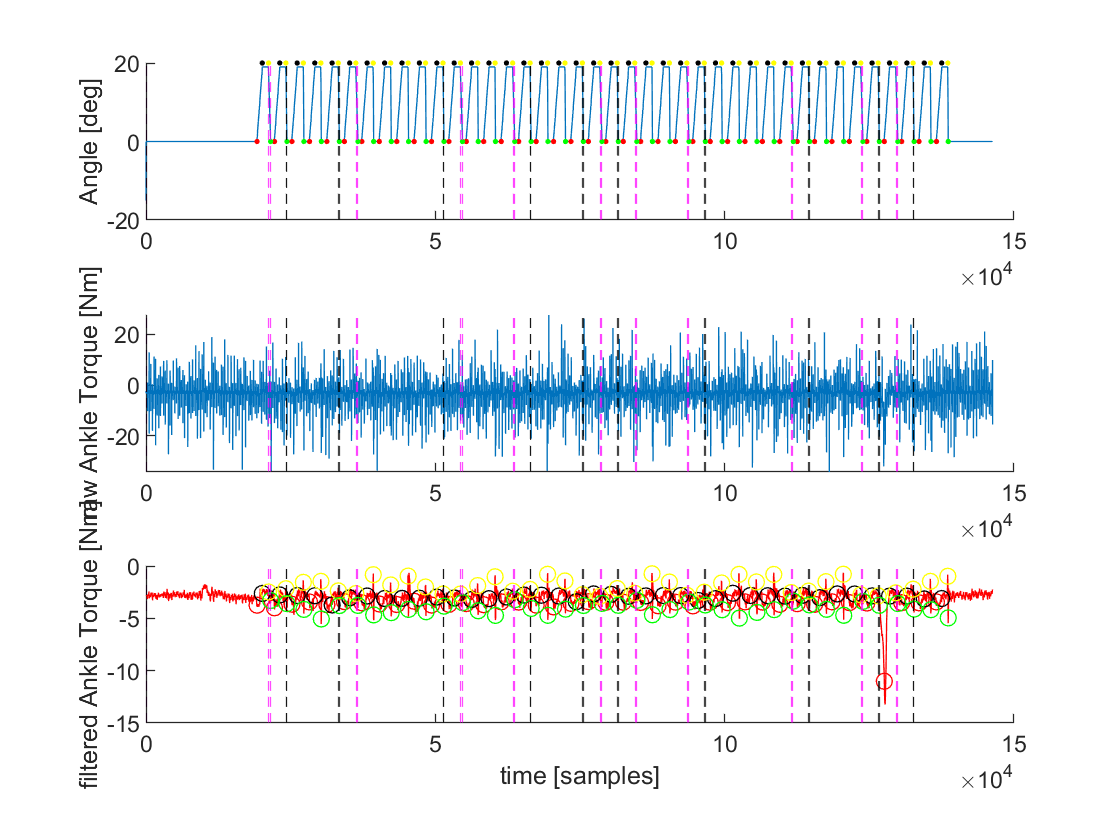

figure(3)
subplot(3,1,1)
hold on
plot(angle_data)%_resampled) 
ylabel('Angle [deg]')
plot (index_ev1,0,'r.')
plot (index_ev2,20,'k.')
plot (index_ev3,20,'y.')
plot (index_ev4,0,'g.')
%plot(rom_com50(:,1))
for tx=1:40
    jj = xline(rom_com50(tx,1), 'm--');
    jj2 = xline(rom_com50(tx,2), 'm--');
    ww = xline(rom_com100(tx,1), 'k--');
    ww2 = xline(rom_com100(tx,2), 'k--');
end
subplot(3,1,2)
hold on
plot(channel1_scaled)
for tx=1:40
    jj = xline(rom_com50(tx,1), 'm--');
    jj2 = xline(rom_com50(tx,2), 'm--');
    ww = xline(rom_com100(tx,1), 'k--');
    ww2 = xline(rom_com100(tx,2), 'k--');
end
ylabel('raw Ankle Torque [Nm]')
subplot(3,1,3)
hold on
plot(channel1_scaled_window,'r')
plot (index_ev1,channel1_scaled_window(index_ev1),'ro')
plot (index_ev2,channel1_scaled_window(index_ev2),'ko')
plot (index_ev3,channel1_scaled_window(index_ev3),'yo')
plot (index_ev4,channel1_scaled_window(index_ev4),'go')
for tx=1:40
    jj = xline(rom_com50(tx,1), 'm--');
    jj2 = xline(rom_com50(tx,2), 'm--');
    ww = xline(rom_com100(tx,1), 'k--');
    ww2 = xline(rom_com100(tx,2), 'k--');
end
ylabel('filtered Ankle Torque [Nm]')
xlabel('time [samples]')


% clear variables
clear a a0 a1 b b0 b1 c ciao  L1a L2a i ii j l i7 i8 m mm n ttmg ttsol ty
% load('PT_new.mat')
% peaktorque = vertcat(peaktorque,TSRT_mechanics);
% save("PT_new",'peaktorque')

#### Notes

Adjustments in the 5%MVC threshold needed to be done in some participants, the reasons are slightly increased background noise (constant throught the trial, not muscle activation) or very low MVC RMS values in which even slight changes in background noises can cause the threshold to be reached. The minimum increase in the threshold that could increase the number of included trials was chosen, 8.5% was the maximum used.

5108/5116/5110/5216 -  Threshold was increased to 6.5%.

5105/5113/5119/5218 - Threshold was increased to 7%.

5106/5112/ -  Threshold was increased to 8.5%.

5216 has clear electrical spikes in some trials, they were discarded. 

5217 has emg onset very close to neutral position, the vars angles_of_catch_sol2 and mg2 have to be multiplied by -1 (a small shift in offset turned the values slightly negative. Additionally, the conditions at lines 867/879 have to be changed to >0 to perform the regression analysis. 

To check emg pre stretch/MVC EMG:

maxs_emgrms_interval_plantar_sol_mw./emgrms_mvc_sol

maxs_emgrms_interval_plantar_mg_mw./emgrms_mvc_mg